current = out.current1.Data;
voltage = out.voltage.Data;
time = out.tout;
soc = out.soc.Data;




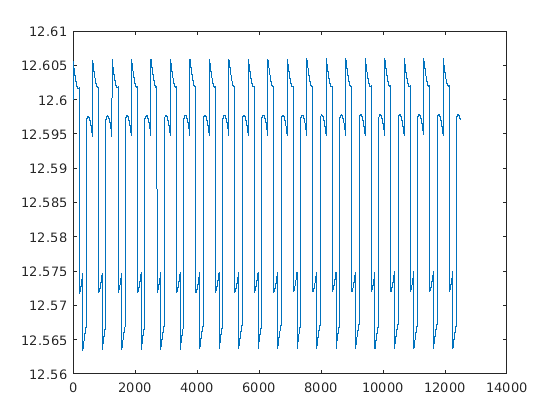

load('batteryModelSfun.mat');
load('soc_ocv_new.mat');

%simOut = sim('batteryMine');

%soc = simOut.soc.Data;
%current = simOut.current.Data;
%voltage = simOut.voltage.Data;
%time    = simOut.tout;

load('current.mat');
load('voltage.mat');
load('time.mat');
load('soc.mat');

plot(voltage);

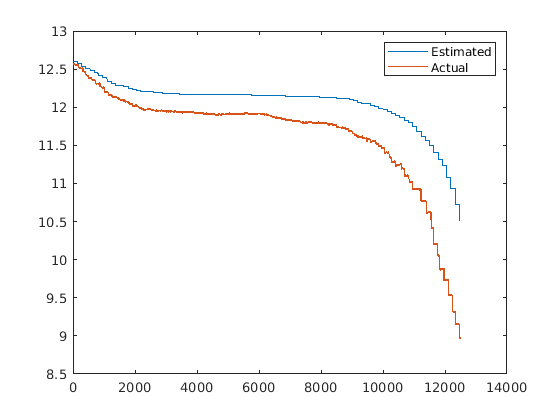

dt = .01;

z   = battery.z;
ir  = battery.Ir;
h   = battery.h;

n   = battery.n;
Q   = battery.Q;
g   = battery.g;
M0  = battery.M0;
M   = battery.M;
R0  = battery.R0;
R1  = battery.R1;
C1  = battery.C1;
EOD = battery.EOD;

Imat = exp(-dt/(R1*C1));
Hmat = exp(-abs((n*g*dt)/Q));

x = [z ; ir ; h];

A = [1 0 0 ; 0 Imat 0 ; 0 0 Hmat];

B = [-n*dt/Q 0 ; (1-Imat) 0 ; 0 (Hmat-1)];

C = [getOCV(z, soc_ocv) -R1 M];

D = [-R0 M0];

y   = zeros(length(voltage), 1);
irs = zeros(length(time), 1);
hs  = zeros(length(time), 1);
zs  = zeros(length(time), 1);


for k = 1:length(time)
    u = [current(k) ; sign(current(k))];
    
    w = [normrnd(0, .01) ; normrnd(0, .002) ; normrnd(0, .002)];
    v = normrnd(0, .001);
    
    x_dot = A*x + B*u + w;
    zs(k) = x_dot(1);
    irs(k) = x_dot(2);
    hs(k) = x_dot(3);

    C = [getOCV(x_dot(1), soc_ocv)/x_dot(1) -R1 M];
    
    y(k) = 3* (C*x_dot + D*u + v);
    
    x = x_dot;
end

plot(voltage); hold on;
plot(y);
legend('Estimated', 'Actual');
hold off;

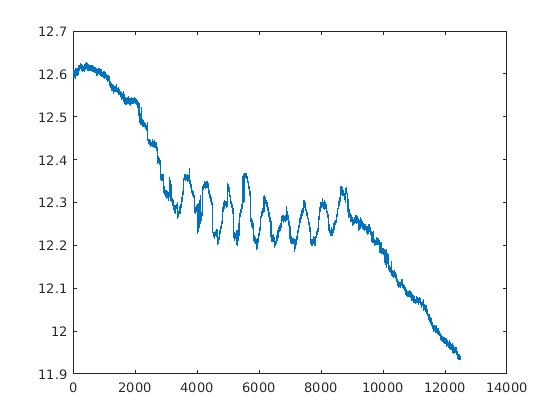

plot(y);

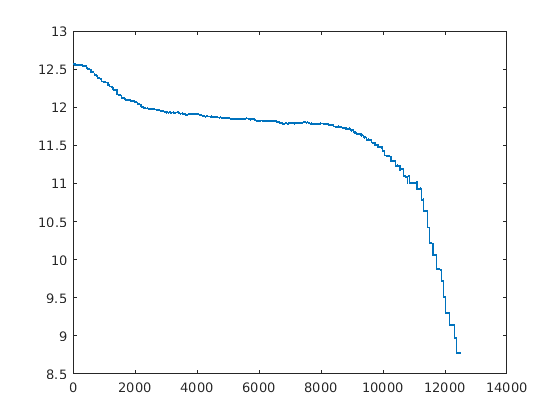

V = zeros(length(time),1);

for k=1:length(time)
    u = [current(k) ; sign(current(k))];
    [x,v] = stepSimulation(x,A,B,C,D,u, soc_ocv, R1, M);
    V(k) = v;
end
plot(V);

function ocv = getOCV(z, soc_ocv)
    
    soc = (z + 31.8816) /(1.0 + 31.8816);
    if soc < 0.0
        soc = 0;
    elseif soc > 1.0
        soc = 1.0;
    end
    
    idx = ceil(soc*100) +1;
    
    if idx > 101
        idx = 101;
    elseif idx < 1
        idx = 1;
    end
    
    ocv = soc_ocv(idx);
end


function [x,y] = stepSimulation(x, A, B, C, D, u, soc_ocv, R1, M)
    w = [normrnd(0, .01) ; normrnd(0, .002) ; normrnd(0, .002)];
    v = normrnd(0, .001);
    
    x_dot = A*x + B*u + w;

    C = [getOCV(x_dot(1), soc_ocv)/x_dot(1) -R1 M];
   
    y = 3* (C*x_dot + D*u + v);
    x = x_dot;
    
end

